#### Code to evaluate what threshold for radiation to not calculate daily albedo values below (cutuoff for night and therefore ignore data)

cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\Analyses\ModProcAnalyses\Figures\Figures2to4'
cd data\input\
load('Bflat30min.mat')

## Albedo Threshold sensitivity

% plot(Bflat30min.SolarRad_Wm2)

Bflat30min.SolarRad_Wm2Logical = Bflat30min.SolarRad_Wm2 > 100; % 100 watt threshold for night
Bflat30min.SolarRad_Wm2_filtered = Bflat30min.SolarRad_Wm2.*Bflat30min.SolarRad_Wm2Logical;
Bflat30min.OutRad_sw_Wm2_filtered = Bflat30min.OutRad_sw_Wm2.*Bflat30min.SolarRad_Wm2Logical;
Bflat30min = removevars(Bflat30min, 'SolarRad_Wm2Logical');
BflatDailySum = retime(Bflat30min, "daily", @sum); %use @sum to make sure the NaN's aren't extrapolated
% BflatDailySum = retime(Bflat30min, "daily", 'sum'); %use @sum to make sure the NaN's aren't extrapolated

Albedo100watt = BflatDailySum.OutRad_sw_Wm2_filtered./BflatDailySum.SolarRad_Wm2_filtered;

Bflat30min.SolarRad_Wm2Logical = Bflat30min.SolarRad_Wm2 > 10; % 100 watt threshold for night
Bflat30min.SolarRad_Wm2_filtered = Bflat30min.SolarRad_Wm2.*Bflat30min.SolarRad_Wm2Logical;
Bflat30min.OutRad_sw_Wm2_filtered = Bflat30min.OutRad_sw_Wm2.*Bflat30min.SolarRad_Wm2Logical;
Bflat30min = removevars(Bflat30min, 'SolarRad_Wm2Logical');
BflatDailySum = retime(Bflat30min, "daily", @sum); %use @sum to make sure the NaN's aren't extrapolated
% BflatDailySum = retime(Bflat30min, "daily", 'sum'); %use @sum to make sure the NaN's aren't extrapolated

Albedo10watt = BflatDailySum.OutRad_sw_Wm2_filtered./BflatDailySum.SolarRad_Wm2_filtered;

Bflat30min.SolarRad_Wm2Logical = Bflat30min.SolarRad_Wm2 > 50; % 100 watt threshold for night
Bflat30min.SolarRad_Wm2_filtered = Bflat30min.SolarRad_Wm2.*Bflat30min.SolarRad_Wm2Logical;
Bflat30min.OutRad_sw_Wm2_filtered = Bflat30min.OutRad_sw_Wm2.*Bflat30min.SolarRad_Wm2Logical;
Bflat30min = removevars(Bflat30min, 'SolarRad_Wm2Logical');
BflatDailySum = retime(Bflat30min, "daily", @sum); %use @sum to make sure the NaN's aren't extrapolated
% BflatDailySum = retime(Bflat30min, "daily", 'sum'); %use @sum to make sure the NaN's aren't extrapolated

Albedo50watt = BflatDailySum.OutRad_sw_Wm2_filtered./BflatDailySum.SolarRad_Wm2_filtered;

Bflat30min.SolarRad_Wm2Logical = Bflat30min.SolarRad_Wm2 > 5; % 100 watt threshold for night
Bflat30min.SolarRad_Wm2_filtered = Bflat30min.SolarRad_Wm2.*Bflat30min.SolarRad_Wm2Logical;
Bflat30min.OutRad_sw_Wm2_filtered = Bflat30min.OutRad_sw_Wm2.*Bflat30min.SolarRad_Wm2Logical;
Bflat30min = removevars(Bflat30min, 'SolarRad_Wm2Logical');
BflatDailySum = retime(Bflat30min, "daily", @sum); %use @sum to make sure the NaN's aren't extrapolated
% BflatDailySum = retime(Bflat30min, "daily", 'sum'); %use @sum to make sure the NaN's aren't extrapolated

Albedo5watt = BflatDailySum.OutRad_sw_Wm2_filtered./BflatDailySum.SolarRad_Wm2_filtered;

Bflat30min.SolarRad_Wm2Logical = Bflat30min.SolarRad_Wm2 > 1; % 100 watt threshold for night
Bflat30min.SolarRad_Wm2_filtered = Bflat30min.SolarRad_Wm2.*Bflat30min.SolarRad_Wm2Logical;
Bflat30min.OutRad_sw_Wm2_filtered = Bflat30min.OutRad_sw_Wm2.*Bflat30min.SolarRad_Wm2Logical;
Bflat30min = removevars(Bflat30min, 'SolarRad_Wm2Logical');
BflatDailySum = retime(Bflat30min, "daily", @sum); %use @sum to make sure the NaN's aren't extrapolated
% BflatDailySum = retime(Bflat30min, "daily", 'sum'); %use @sum to make sure the NaN's aren't extrapolated

Albedo1watt = BflatDailySum.OutRad_sw_Wm2_filtered./BflatDailySum.SolarRad_Wm2_filtered;

Bflat30min.SolarRad_Wm2Logical = Bflat30min.SolarRad_Wm2 > 200; % 100 watt threshold for night
Bflat30min.SolarRad_Wm2_filtered = Bflat30min.SolarRad_Wm2.*Bflat30min.SolarRad_Wm2Logical;
Bflat30min.OutRad_sw_Wm2_filtered = Bflat30min.OutRad_sw_Wm2.*Bflat30min.SolarRad_Wm2Logical;
Bflat30min = removevars(Bflat30min, 'SolarRad_Wm2Logical');
BflatDailySum = retime(Bflat30min, "daily", @sum); %use @sum to make sure the NaN's aren't extrapolated
% BflatDailySum = retime(Bflat30min, "daily", 'sum'); %use @sum to make sure the NaN's aren't extrapolated

Albedo200watt = BflatDailySum.OutRad_sw_Wm2_filtered./BflatDailySum.SolarRad_Wm2_filtered;

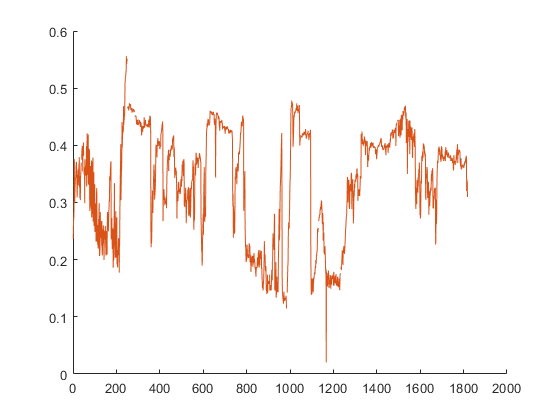

figure
hold on 
plot(Albedo1watt)
plot(Albedo10watt)
% plot(Albedo100watt)
% plot(Albedo200watt)
% plot(Albedo50watt)
% plot(Albedo5watt)
hold off

# Conclusion - could manage with a 5 watt threshold - but regardless of the threshold the albeo does not change mutch.